

graphSet;

repertoire = './'; % Chemin d'acces au code compile (NB: enlever le ./ sous Windows)
executable = 'Exercice7'; % Nom de l'executable (NB: ajouter .exe sous Windows)
input = '7_2_a.in'; % Nom du fichier d'entree de base

cb_gauche = 'harmonique';
cb_droit = 'libre';

output = '7_2_a';
cmd = sprintf('wsl %s%s %s cb_gauche=%s cb_droit=%s  output=%s tfin=%.15g', repertoire, executable, input, cb_gauche,cb_droit,output,14);
disp(cmd);

wsl ./Exercice7 7_2_a.in cb_gauche=harmonique cb_droit=libre  output=7_2_a tfin=14


system(cmd);

	tfin=14
	L=20
	Npoints=1000
	CFL=0.9
	type_u2=const
	u=6
0.02002
0.003003
	ecrire_f=1
	schema=A
	cb_gauche=harmonique
	cb_droit=libre
	A=1
	omega=5
	output=7_2_a
	n_stride=10


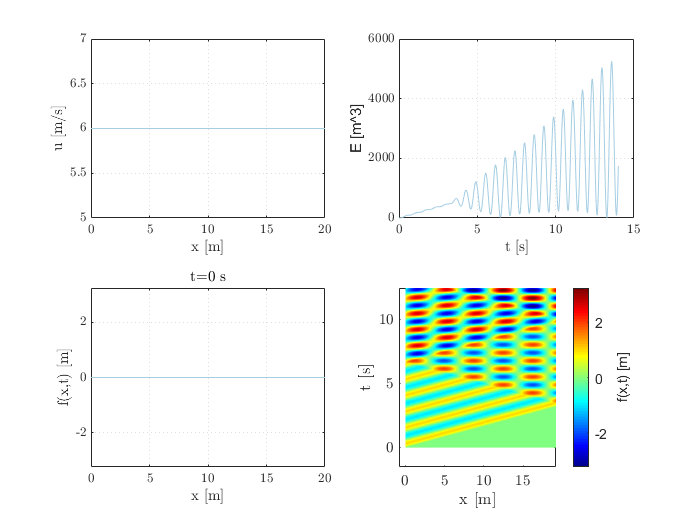

fichier = output;
data = load([fichier,'_u.out']);
x = data(:,1);
u = data(:,2);
data = load([fichier,'_E.out']);
t = data(:,1);
E = data(:,2);
data = load([fichier,'_f.out']);
f = data(:,2:end);

%% Figures %%
%%%%%%%%%%%%%
figure('Name',['Analyse de ' fichier])
subplot(2,2,1)
plot(x,u)
grid
xlabel('x [m]')
ylabel('u [m/s]')

subplot(2,2,2)
plot(t,E)
grid
xlabel('t [s]')
ylabel('E [m^3]')

subplot(2,2,4)
pcolor(x,t,f)
shading interp
colormap jet
c = colorbar;
xlabel('x [m]')
ylabel('t [s]')
ylabel(c,'f(x,t) [m]')

subplot(2,2,3)
h = plot(x,f(1,:));
grid
xlabel('x [m]')
ylabel('f(x,t) [m]')
ht = title('t=0 s');
ylim([min(f(:)),max(f(:))])

% for i=2:length(t)
%     pause(.01)
%     if ~ishandle(h)
%         break % Arrete l'animation si la fenetre est fermee
%     end
%     set(h,'YData',f(i,:))
%     set(ht,'String',sprintf('t=%0.2f s',t(i)))
% end

figure('visible','on')

n = length(t)

n = 468

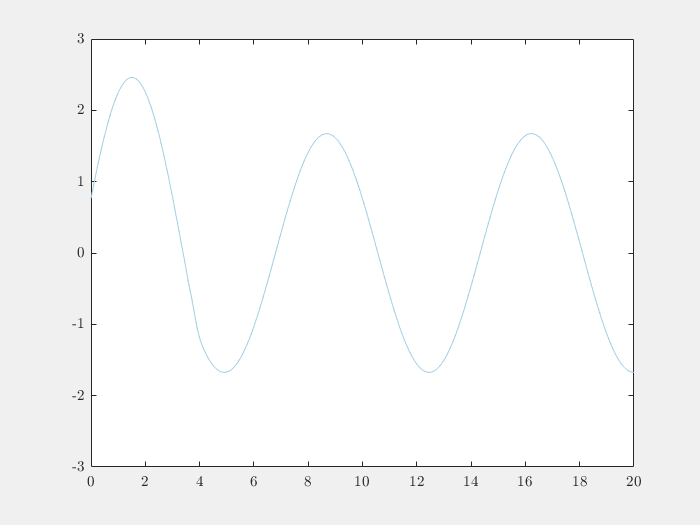

for i=1:n
    
    
    plot(x,f(i,:))
    ylim([-3 3])
    pause(0.005)
end